# Growth Kinetics

clear;
clc;

WT = "/Users/Priya/testoutput/TestMammaryMonolayerWT/results_from_time_0/heterotypicboundary.dat";
heterotypicboundaryWTall = importfile_heterotypicboundaryall(WT);

## Plot Time vs Total Boundary Length

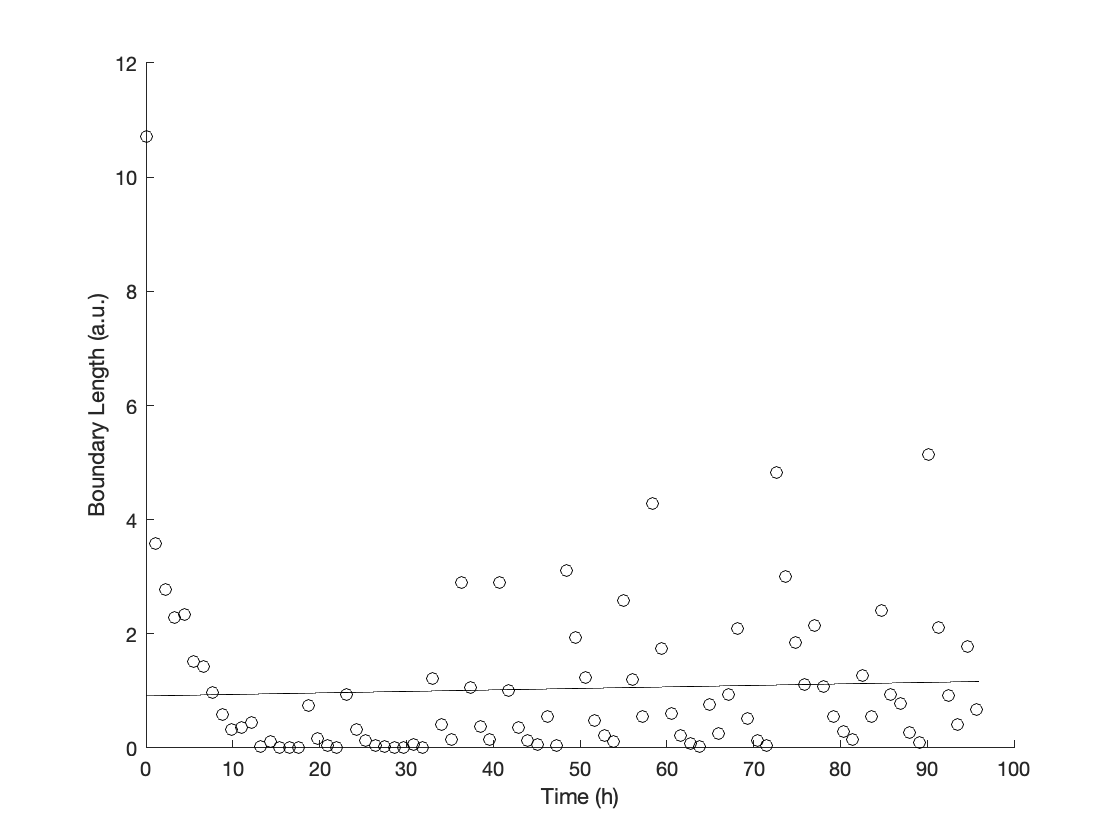

x=table2array(heterotypicboundaryWTall(:,1));

yWT=table2array(heterotypicboundaryWTall(:,3));

figure
hold on

scatter(x(1:11:960), yWT(1:11:960), 'k')
pWT = polyfit(x,yWT,1);
fWT = polyval(pWT,x);
plot(x,fWT, 'k')

hold off

ylabel ('Boundary Length (a.u.)')
xlabel('Time (h)')

%legend({'WT', 'ME B1 KO'})

## Plot Time vs Radius

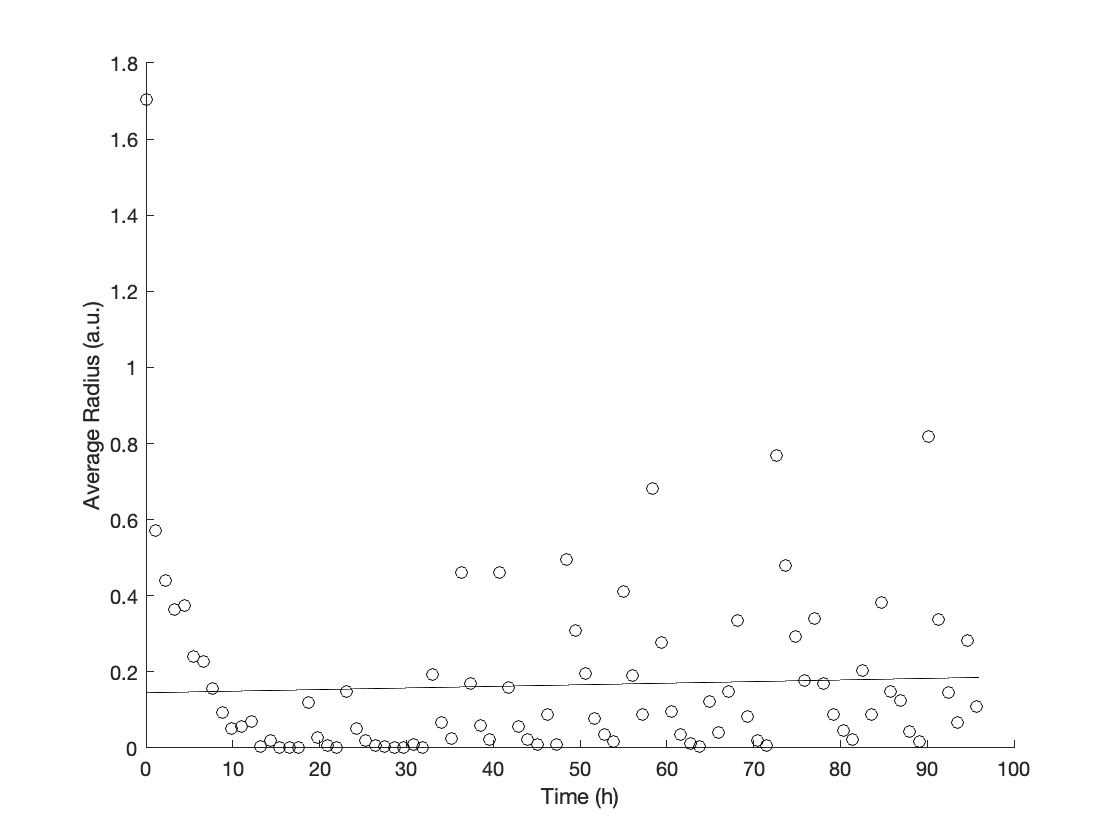

x=table2array(heterotypicboundaryWTall(:,1));

yWT=table2array(heterotypicboundaryWTall(:,3));

diameter = yWT(:,1)./pi;

radius = diameter(:,1)./2;

figure
hold on

scatter(x(1:11:960), radius(1:11:960), 'k')
pWT = polyfit(x,radius,1);
fWT = polyval(pWT,x);
plot(x,fWT, 'k')

hold off

ylabel ('Average Radius (a.u.)')
xlabel('Time (h)')

%legend({'WT', 'ME B1 KO'})

WT = "/Users/Priya/testoutput/TestMammaryMonolayerWT/results_from_time_0/location.dat";
cells = importfile_displacement(WT);
time = double(importfile_time(WT));

celltype = cells(:,1:5:end);
numberofcells (:,1) = transpose(sum(transpose(celltype()) == 'Luminal'));
numberofcells (:,2)= transpose(sum(transpose(celltype()) == 'Myoepithelial'));
numberofcells (:,3) = transpose(sum(transpose(numberofcells())));

## Plot Time vs Number of Cells

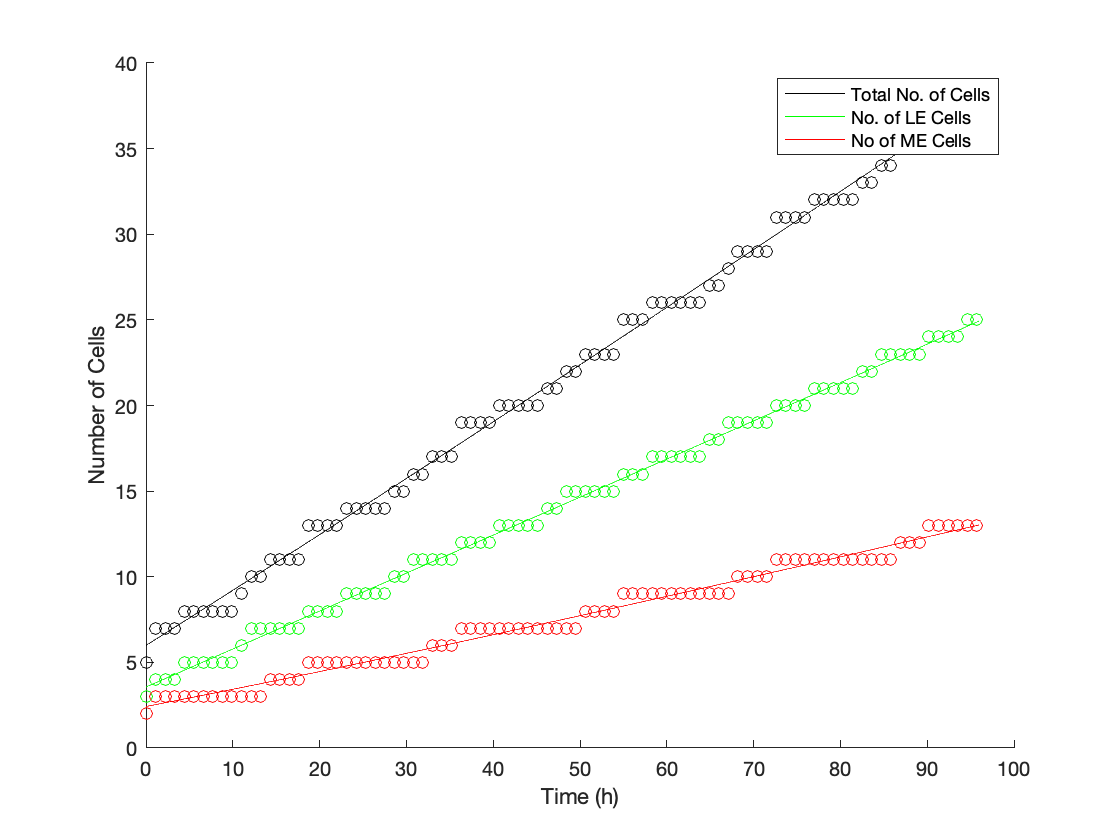

x = time(:,1);

yLE=numberofcells(:,1);

yME=numberofcells(:,2);

yWT=numberofcells(:,3);

figure
hold on

scatter(x(1:11:960), yWT(1:11:960), 'k')
pWT = polyfit(x,yWT,3);
fWT = polyval(pWT,x);
total = plot(x,fWT, 'k');

scatter(x(1:11:960), yLE(1:11:960), 'g')
pLE = polyfit(x,yLE,3);
fLE = polyval(pLE,x);
LE = plot(x,fLE, 'g');

scatter(x(1:11:960), yME(1:11:960), 'r')
pME = polyfit(x,yME,3);
fME = polyval(pME,x);
ME = plot(x,fME, 'r');

hold off

ylabel ('Number of Cells')
xlabel('Time (h)')
legend([total, LE, ME],'Total No. of Cells', 'No. of LE Cells', 'No of ME Cells')

### Calculate the `R` values and the significance levels (probabilities)

format long
[R,P] = corrcoef(x,yWT)

R =    1.000000000000000   0.998300171782663
   0.998300171782663   1.000000000000000


P =      1     0
     0     1


## Plot Number of Cells vs Radius

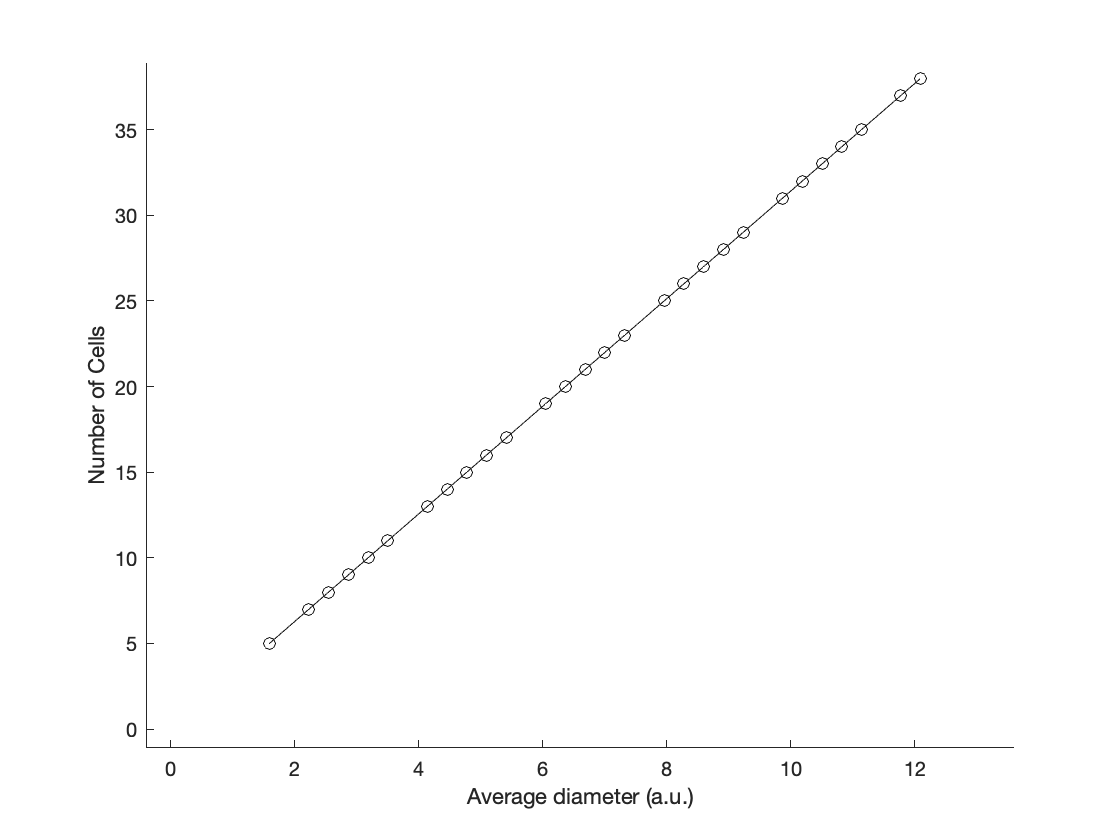

diameter = yWT(:,1)./pi;
yWT=numberofcells(:,3);

figure
hold on

scatter(diameter(1:11:960), yWT(1:11:960), 'k')
pWT = polyfit(diameter,yWT,1);
fWT = polyval(pWT,diameter);
total = plot(diameter,fWT, 'k');

hold off

ylabel ('Number of Cells')
xlabel('Average diameter (a.u.)')

#### Calculate gradient of slope

slope = pWT(1)

slope =    3.141592653589791


## Plot number of LE and ME cells

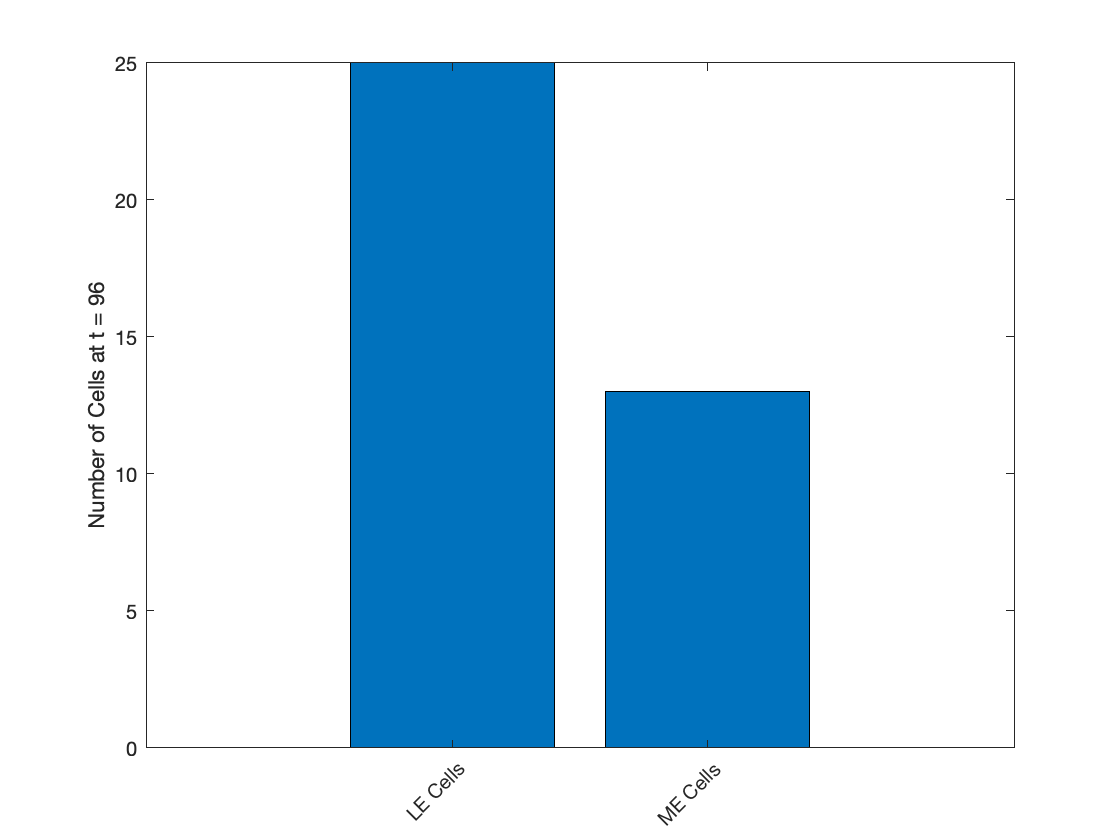

x = [1 2];
y = [numberofcells(end,1),numberofcells(end,2)];

bar(x,y)
ylabel('Number of Cells at t = 96')
ax = gca;
ax.XTick = [1 2]; 
ax.XTickLabels = {'LE Cells', 'ME Cells'};
ax.XTickLabelRotation = 45;